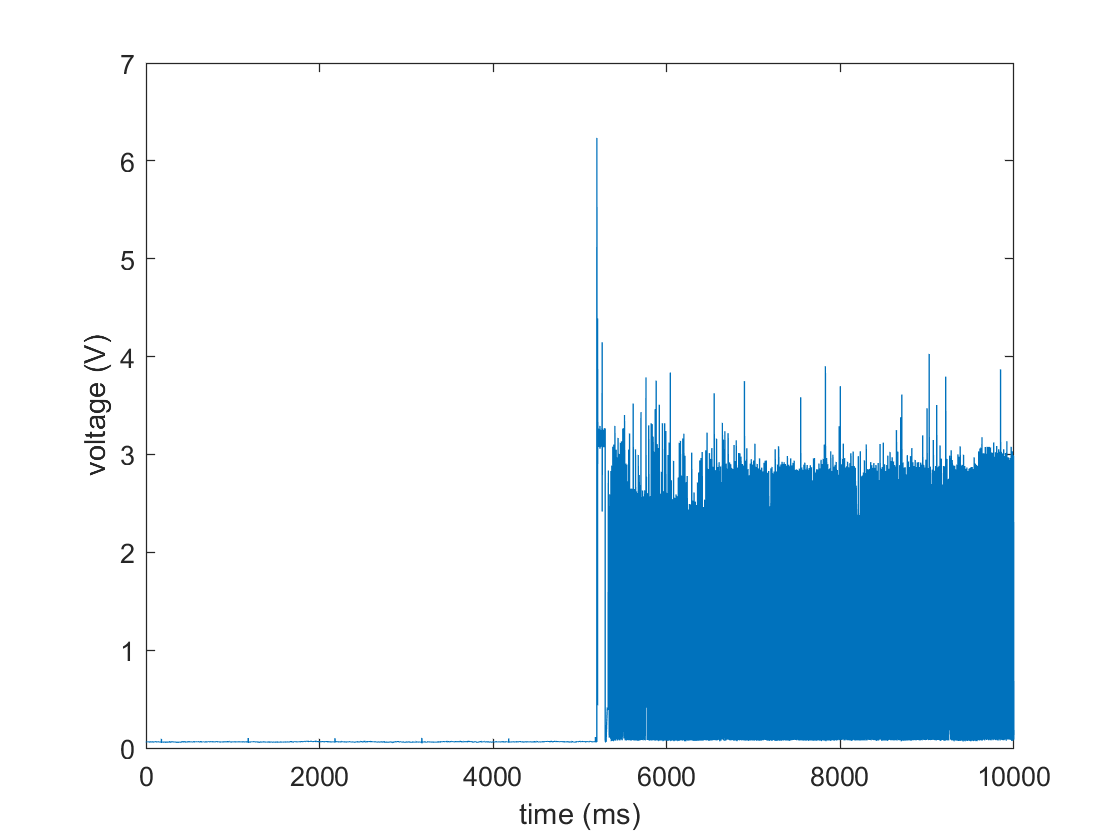

% This code is to plot the values from the oscilloscope
% The data format is CSV
% ----------------------------------------------------------------------

%initialnize
sampleInterval = 0.1;   % The unite is in 'ms'; This value is in 'Sample Interval' in the csv file

% read CSV file
% load the data from 22 row to the end row, from second column to end colunm
% note the first row and colunm is 0
% osc = csvread('D:\Major Project\Code Project\Wareform Analysis\OSC\CMT\16092020 trial2 voltage.csv',21,1);
osc = csvread('D:\16092020 trial2 voltage.csv',21,1);

% extract the data from the 'osc'
voltageData = osc(:, 1);

voltageData_interv = [];
for i=1:2:length(voltageData)
    voltageData_interv = [voltageData_interv, voltageData(i,:)];
end

timeStamp = length(voltageData_interv);

%----------------------------

% Load the video
v = VideoReader(['D:\16092020 trial2 0-10000 30fps.mp4']);

% plot
X = (1 : timeStamp) * sampleInterval;
figure
% h_sp1 = subplot(2,1,1);
% plot(X,voltageDataCh1);
% ylabel('Current (A)')
% h_sp2 = subplot(2,1,2); 
plot(X,voltageData_interv);
ylabel('voltage (V)')
xlabel('time (ms)')

% linkaxes([h_sp1, h_sp2], 'x');